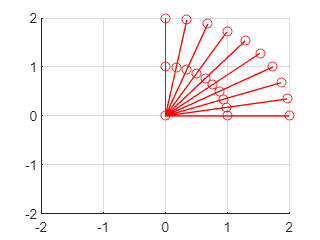

clc;
clear;
tht_1=input("theta 1:");
tht_2=input("theta 2:");
tht_3=input("theta 3:");
l1 =1;
l2=1;
tht1=linspace(0,tht_1,10);
tht2=linspace(0,tht_2,10);
tht3=linspace(0,tht_3,10);

tht=[tht1; tht2; tht3];

for i= 1:length(tht1)
DH=[0 0 0 tht(1,i);
    l1 0 0 tht(2,i);
    l2 0 0 tht(3,i)];

a=DH(:,1);
alp=DH(:,2);
d=DH(:,3);

T2=1;
T3=1;

for j=1:3
T=[  cosd(tht(j,i))                 -sind(tht(j,i))                  0                   a(j);
    sind(tht(j,i))*cosd(alp(j))  cosd(tht(j,i))*cosd(alp(j)) -sind(alp(j))  -sind(alp(j))*d(j);
    sind(tht(j,i))*sind(alp(j))  cosd(tht(j,i))*sind(alp(j))  cosd(alp(j))   cosd(alp(j))*d(j);
           0                               0                       0                  1         ];

if(j<3)
    T2=T2*T;
end
    if(j<4)
        T3=T3*T;
    end

    end

x1=T2(1,4);
y1=T2(2,4);

x2=T3(1,4);
y2=T3(2,4);

x=[0 x1 x2];
y=[0 y1 y2];

figure(1);
hold on

plot(x,y,"-ro","LineWidth",0.5);
grid on;
axis( [-2 2 -2 2]);

hold off
end